dataset = load("milltraining.mat")

dataset = struct with fields:
    milltraining: [133×7 table]



dataset = dataset.milltraining

dataset = 133×7 table
         smcAC              smcDC            vib_table         vib_spindle         AE_table          AE_spindle       FlankwearVB
    _______________    _______________    _______________    _______________    _______________    _______________    ___________

    {9000×1 double}    {9000×1 double}    {9000×1 double}    {9000×1 double}    {9000×1 double}    {9000×1 double}          1    
    {9000×1 double}    {9000×1 double}    {9000×1 double}    {9000×1 double}    {9000×1 double}    {9000×1 double}        NaN    
    {9000×1 double}    {9000×1 double}    {9000×1 double}    {9000×1 double}    {9000×1 double}    {9000×1 double}          1    
    {9000×1 double}    {9000×1 double}    {9000×1 double}    {9000×1 double}    {9000×1 double}    {9000×1 double}          1    
    {9000×1 double}    {9000×1 double}    {9000×1 double}    {9000×1 double}    {9000×1 double}    {9000×1 double}          1    
    {9000×1 double}    {9000×1 double}    {9000×1 double}    {9000×

dataset([11,89], :) = [];

dataset_wo_NaN = rmmissing(dataset);



%Print bar Chart of 1s 2s and 3s
y = dataset_wo_NaN.FlankwearVB;

% Count how many 1/2/3
classes = [1 2 3];
counts = arrayfun(@(c) sum(y == c), classes);

% Print counts in Command Window
disp("Class counts (runs):")

Class counts (runs):


disp(table(classes', counts', 'VariableNames', {'FlankwearClass','Count'}))

    FlankwearClass    Count
    ______________    _____

          1            61  
          2            44  
          3            15  



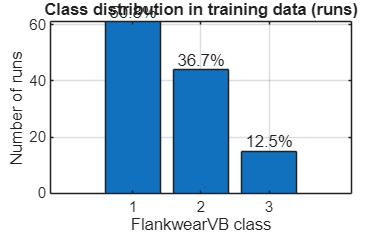


% Bar chart
figure;
bar(classes, counts);
xticks(classes);
xlabel('FlankwearVB class');
ylabel('Number of runs');
title('Class distribution in training data (runs)');
grid on;

% Optional: show percentages on top of bars
pct = counts / sum(counts) * 100;
text(classes, counts, compose('%.1f%%', pct), ...
    'HorizontalAlignment','center', 'VerticalAlignment','bottom');

%remove the first 3 seconds

% Define the number of data points to remove (N)
N = 3000; 

% Define the starting index for the data you want to KEEP
START_INDEX = N + 1; 

% List the columns containing the time series data (signals)
signal_cols = {'smcAC', 'smcDC', 'vib_table', 'vib_spindle', 'AE_table', 'AE_spindle'};

% Get the number of rows (runs) in your table
num_rows = size(dataset_wo_NaN, 1);

% Iterate through every row (i)
for i = 1:num_rows
    
    % Iterate through every signal column (j)
    for j = 1:length(signal_cols)
        
        colName = signal_cols{j};
        
        % 1. Access the signal vector from the cell array using curly braces {}
        current_signal = dataset_wo_NaN.(colName){i};
        
        % 2. Crop the vector: keep from START_INDEX to the end.
        %    The 'end' keyword automatically uses the last index of the vector.
        cropped_signal = current_signal(START_INDEX : end);
        
        % 3. Assign the cropped vector back into the table cell
        dataset_wo_NaN.(colName){i} = cropped_signal;
    end
end

dataset_wo_NaN  

dataset_wo_NaN = 120×7 table
         smcAC              smcDC            vib_table         vib_spindle         AE_table          AE_spindle       FlankwearVB
    _______________    _______________    _______________    _______________    _______________    _______________    ___________

    {6000×1 double}    {6000×1 double}    {6000×1 double}    {6000×1 double}    {6000×1 double}    {6000×1 double}         1     
    {6000×1 double}    {6000×1 double}    {6000×1 double}    {6000×1 double}    {6000×1 double}    {6000×1 double}         1     
    {6000×1 double}    {6000×1 double}    {6000×1 double}    {6000×1 double}    {6000×1 double}    {6000×1 double}         1     
    {6000×1 double}    {6000×1 double}    {6000×1 double}    {6000×1 double}    {6000×1 double}    {6000×1 double}         1     
    {6000×1 double}    {6000×1 double}    {6000×1 double}    {6000×1 double}    {6000×1 double}    {6000×1 double}         2     
    {6000×1 double}    {6000×1 double}    {6000×1 double}   

T_clean = dataset_wo_NaN; % Use the cleaned/cropped table

% Define segmentation parameters
WINDOW_SIZE = 512; % L
HOP_SIZE = 256;    % S (50% overlap)

% List the signal columns to process
signal_cols = {'smcAC', 'smcDC', 'vib_table', 'vib_spindle', 'AE_table', 'AE_spindle'};

% Initialize a new table to store the final segments
% Note: We include an extra variable for 'Row_Label' to track the origin of the segment
varTypes = repmat({'cell'}, 1, length(signal_cols));
T_segments = table('Size', [0, length(signal_cols) + 2], ...
                   'VariableTypes', [varTypes, {'double', 'double'}], ...
                   'VariableNames', [signal_cols, {'Flankwear_Label', 'Row_Label'}]);

segment_row_idx = 0; % Counter for the new segment rows

% --- Loop through every original run (row) ---
for i = 1:size(T_clean, 1)
    
    % Get the Flankwear label and the row index (for tracking)
    flankwear_label = T_clean.FlankwearVB(i);
    
    % FIX: The original index of the row in the 'dataset_wo_NaN' table.
    % The output statement 'row_label = i' was removed.
    row_label = i; 
    
    % Use the length of one signal (assuming all are the same length after cropping)
    signal_length = length(T_clean.smcAC{i}); 
    
    % --- Sliding Window Loop ---
    % Stop when the window cannot fit a full WINDOW_SIZE segment
    for start_idx = 1 : HOP_SIZE : (signal_length - WINDOW_SIZE + 1)
        end_idx = start_idx + WINDOW_SIZE - 1;
        
        segment_row_idx = segment_row_idx + 1;
        
        % 1. Store the label and origin row index in the new table
        T_segments.Flankwear_Label(segment_row_idx, 1) = flankwear_label;
        T_segments.Row_Label(segment_row_idx, 1) = row_label; % Keep track of the source run
        
        % 2. Loop through all signal columns to extract segments
        for k = 1:length(signal_cols)
            colName = signal_cols{k};
            
            % Extract the current long signal vector
            current_signal_vector = T_clean.(colName){i}; 
            
            % Extract the fixed-length segment
            segment = current_signal_vector(start_idx : end_idx);
            
            % Store the segment vector into the new table cell
            T_segments.(colName){segment_row_idx, 1} = segment;
        end
    end
end


disp(['Finished segmentation. Total segments created: ', num2str(segment_row_idx)]);

T_segments

%clean the segments


% --- Recalculate statistics on the long, cropped signals (T_clean) ---

% List the signal columns
signal_cols = {'smcAC', 'smcDC', 'vib_table', 'vib_spindle', 'AE_table', 'AE_spindle'};
num_signals = length(signal_cols);

% Add new columns to T_clean to store the run-specific statistics (optional, but helpful)
% These columns will store a struct/table of the mu and sigma for each run
T_clean.Stats = cell(size(T_clean, 1), 1); 

% Iterate through every original run (row)
for i = 1:size(T_clean, 1)
    
    run_stats = struct();
    
    % Loop through every signal column
    for k = 1:num_signals
        colName = signal_cols{k};
        
        % Get the full cropped signal vector for this run
        signal_vector = T_clean.(colName){i}; 
        
        % Calculate and store the run-specific mean and std deviation
        run_stats.(colName).mu = mean(signal_vector);
        run_stats.(colName).sigma = std(signal_vector);
    end
    
    % Store the calculated statistics back into the table
    T_clean.Stats{i} = run_stats;
end



T_clean.Stats{1}.smcAC

%remove the outlier segments

num_rows = size(T_segments,1)

segments_idx_to_remove = zeros(num_rows,1)

for i = 1:num_rows
    
    for j = 1:length(signal_cols)
    % 1. Get the current signal name from the cell array.
    % We use {j} instead of (j) to extract the string content.
    colName = signal_cols{j};

    % 2. Get the index of the parent run from the segment table (assuming 
    % you are in a loop where 'i' is the segment index).
    % **Note:** You must be inside a loop to access a single row index.
    % Let's assume the current segment's index is 'i'.
    segment_index = i; 
    
    parent_run_index = T_segments.Row_Label(segment_index);

    % 3. Index into the T_clean table to get the run's statistics structure
    run_stats = T_clean.Stats{parent_run_index};

    % 4. Access the average using Dynamic Field Names
    % We use (colName) instead of .colName or .param
    average_col = run_stats.(colName).mu;
    std_dev_col = run_stats.(colName).sigma;

    upper_limit = average_col + std_dev_col*0.66;
    lower_limit = average_col - std_dev_col*0.66;
    
    current_mean = mean(T_segments.(colName){i});

    if current_mean > upper_limit || current_mean < lower_limit
        segments_idx_to_remove(i) = 1;
        break
    end

    end

end

idx = find(segments_idx_to_remove)

T_segments(idx,:)=[]




diagnosticFeatureDesigner

% %plot random rows for comparison
% 
% %milltraining = load("milltraining.mat");
% 
% 
% outputFile = "overview_plots_segments.pdf";
% 
% % Remove old file if it exists
% if isfile(outputFile)
%     delete(outputFile);
% end
% 
% for j = 1:100
% 
%     index = randi(1728);
% 
%     fig = figure('Visible','off');   % prevents windows from popping up
% 
%     % --- Row title (optional) ---
%     sgtitle(['All signals for row ' int2str(index), ', Flankwear: ', int2str(T_segments.Flankwear_Label(index))], 'FontSize', 14);
% 
%     % 1 — smcAC
%     subplot(3,2,1)
%     plot(T_segments.smcAC{index});
%     title('smcAC');
%     xlabel('Sample'); ylabel('Amplitude');
% 
%     % 2 — smcDC
%     subplot(3,2,2)
%     plot(T_segments.smcDC{index});
%     title('smcDC');
%     xlabel('Sample'); ylabel('Amplitude');
%     ylim([0,15]);
% 
%     % 3 — vib_table
%     subplot(3,2,3)
%     plot(T_segments.vib_table{index});
%     title('vib\_table');
%     xlabel('Sample'); ylabel('Amplitude');
% 
%     % 4 — vib_spindle
%     subplot(3,2,4)
%     plot(T_segments.vib_spindle{index});
%     title('vib\_spindle');
%     xlabel('Sample'); ylabel('Amplitude');
% 
%     % 5 — AE_table
%     subplot(3,2,5)
%     plot(T_segments.AE_table{index});
%     title('AE\_table');
%     xlabel('Sample'); ylabel('Amplitude');
% 
%     % 6 — AE_spindle
%     subplot(3,2,6)
%     plot(T_segments.AE_spindle{index});
%     title('AE\_spindle');
%     xlabel('Sample'); ylabel('Amplitude');
% 
%     % Export page to PDF (append mode)
%     exportgraphics(fig, outputFile, "Append", true);
% 
%     close(fig); % close to avoid memory buildup
% end
% 
% disp("Done! Saved all figures to " + outputFile);
% 
